# This is the live script for ESE 6190 HW6 Explicit MPC Exercise 2

clear all
clc

## 2.6 declare the decision variable and parameter variables as symbolic variables

z = sdpvar(1, 1);
x = sdpvar(2, 1);

## 2.7 Use the symbolic variables to define the objective and constraints of mpQP

J = 0.5*z(1)^2 + 2*x(1)*z(1) + x(2)^2;
% Include -5 <= x <= 5 in C to restrict the plots to this region.
C = [ z(1) <= 1 + x(1), -z(1) <= 1-x(2), -5 <= x <= 5];

## 2.8 convert the problem into the format of the MPT3 toolbox and call the routine to solve the multi-parametric program.

mpQP = Opt(C, J, x, z);
solution = mpQP.solve();

mpt_plcp: 3 regions


## 2.9 visualize the solution, plot the critical regions, the z*(x1; x2), and J*(x1; x2)

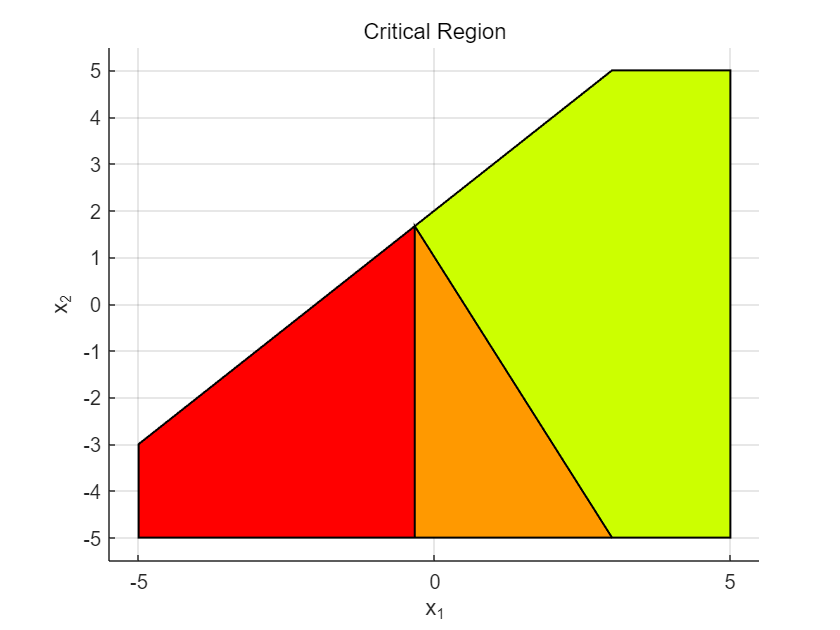

figure;
hold on
title('Critical Region')
xlabel('x_1')
ylabel('x_2')
solution.xopt.plot();

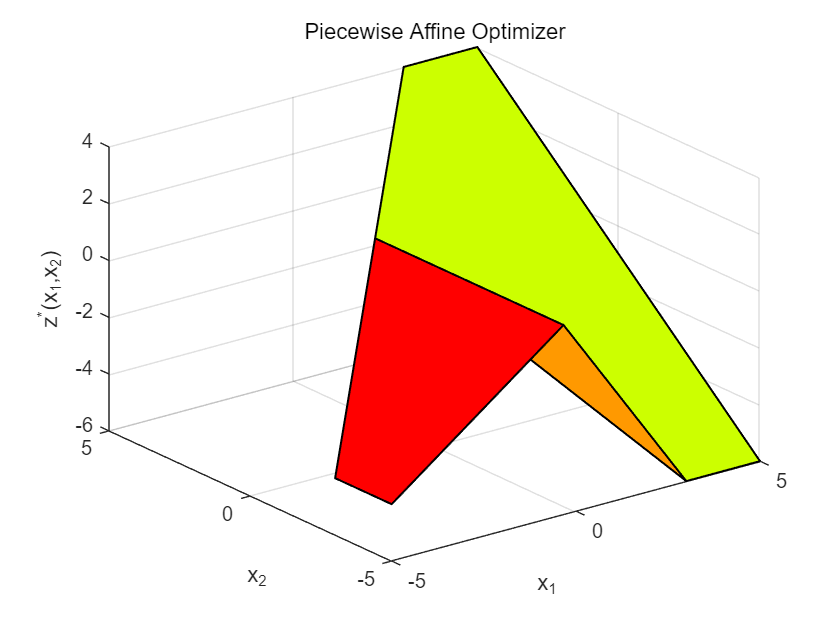

figure;
hold on
xlabel('x_1')
ylabel('x_2')
zlabel('z^*(x_1,x_2)')
title('Piecewise Affine Optimizer')
solution.xopt.fplot('primal');

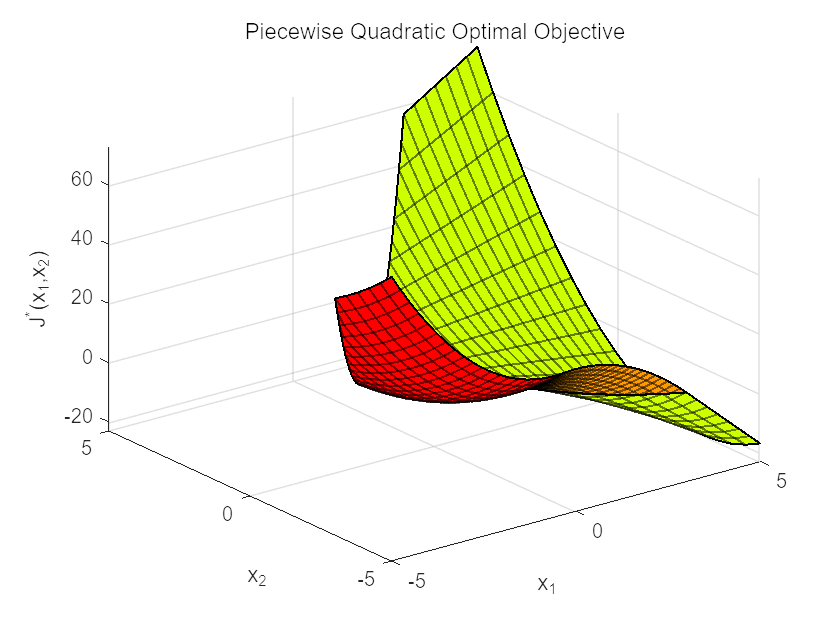

figure;
hold on
xlabel('x_1')
ylabel('x_2')
zlabel('J^*(x_1,x_2)')
title('Piecewise Quadratic Optimal Objective')
solution.xopt.fplot('obj');